 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3   -6.006327e-01     0.000e+00     1.000e+00     0.000e+00     1.051e+00  
    1           6   -2.021642e+00     0.000e+00     1.000e+00     1.061e+00     1.022e+00  
    2           9   -3.046470e+00     0.000e+00     1.000e+00     2.188e+00     3.767e-01  
    3          12   -3.188646e+00     0.000e+00     1.000e+00     4.073e-01     3.234e-01  
    4          15   -3.618766e+00     0.000e+00     1.000e+00     1.749e+00     1.870e-01  
    5          18   -3.956402e+00     0.000e+00     1.000e+00     2.398e+00     1.060e-01  
    6          21   -4.149718e+00     1.481e-02     1.000e+00     2.304e+00     4.791e-02  
    7          24   -4.149635e+00     5.479e-06     1.000e+00     2.137e-03     8.770e-04  
    8          27   -4.149635e+00     6.981e-13     1.000e+00     7.908e-07     9.

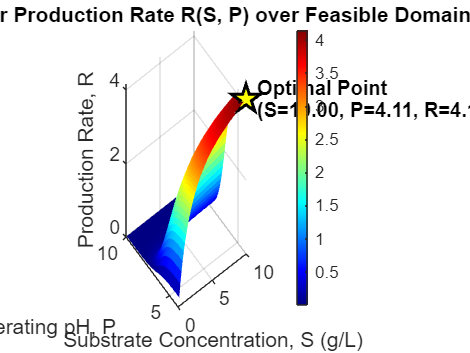

% 1. Define process constants structural array (Requirement a)
params.V_max = 5.0;
params.K_m   = 2.0;
params.pK_a  = 6.5;
params.c_s   = 0.5;
params.c_p   = 1.2;

% 2. Define constraint bounds structural array (Requirement a)
bounds.S_min = 0.1;
bounds.S_max = 10.0;
bounds.P_min = 4.0;
bounds.P_max = 10.0;
bounds.C_max = 15.0;

% 3. Define initial guess optimization parameters structural array (Requirement a)
opts.S0 = 2.0;
opts.P0 = 7.0;

% 4. Run the main function
[S_opt, P_opt, R_max] = optimizeBioreactor(params, bounds, opts);


% Display results
fprintf('\n--- Optimization Results ---\n');


--- Optimization Results ---


fprintf('Optimal Substrate (S_opt): %.4f g/L\n', S_opt);

Optimal Substrate (S_opt): 10.0000 g/L


fprintf('Optimal pH (P_opt):        %.4f\n', P_opt);

Optimal pH (P_opt):        4.1132


fprintf('Max Production Rate (R):   %.4f units/hr\n', R_max);

Max Production Rate (R):   4.1496 units/hr
